# Writing an ODE Function, part 3

Do not edit. This code solves the ODE system and visualizes the solution.

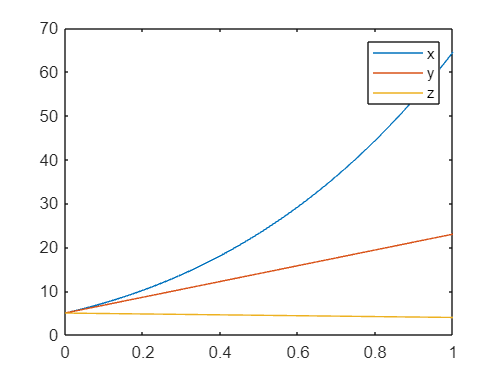

tRange = [0 1];
Y0 = [5;5;5];
[tSol,YSol] = ode45(@myODEfun,tRange,Y0);
% visualize solution
plot(tSol,YSol(:,1))
hold on
plot(tSol,YSol(:,2))
plot(tSol,YSol(:,3))
hold off
legend("x","y","z")

## Task 3

The output of the ODE function must be a column  vector. Recall that you can create column vectors by separating each  element with a semicolon:

`c` `=` `[``a``;``b``]` 

Task

In the local function `myODEfun`, complete the expression for `dYdt` by creating a column vector containing `dxdt`, `dydt`, and `dzdt`.

function dYdt = myODEfun(t,Y)
x = Y(1);
y = Y(2);
z = Y(3);

dxdt = x + 2*y + z;
dydt = 18;
dzdt = -1;

% TODO - Complete expression for dYdt
% dYdt is a column vector containing dxdt, dydt, and dzdt
dYdt=[dxdt;dydt;dzdt];
end